## ** Dermatological Lighting and Neural Networks**

%Model you want to run
model1 = alexnet;  
%model1 = vgg16;
%model1 = vgg19;

**Loading polarized image data, benign and malignant and displaying table of labels and counts**

%Load Data
dataFolder = './data'; %All Data
%dataFolder= './data1';  %Non-Polar
%dataFolder= './data2'; %Polar
categories = {'Benign', 'Malignant'};
imds = imageDatastore(fullfile(dataFolder, categories), 'LabelSource', 'foldernames','IncludeSubfolders',true);
tbl = countEachLabel(imds);
disp (tbl)

      Label      Count
    _________    _____

    Benign        299 
    Malignant     248 



**Even out the dataset to have same number of images per category**

%Minimum Set Count set up
minSetCount = min(tbl{:,2});

% Use splitEachLabel method to trim the set.
imds = splitEachLabel(imds, minSetCount, 'randomize');

%Evening out the set of images
countEachLabel(imds)

ans = 2×2 table
      Label      Count
    _________    _____

    Benign        248 
    Malignant     248 


**Split data into training and validation sets using 70/30 split, Display training and validation set counts. **

%Set up for the training
imds.ReadFcn = @(filename)readAndPreprocessImage(filename);

[trainingSet, validationSet] = splitEachLabel(imds, 0.7, 'randomized');

countEachLabel(trainingSet)

ans = 2×2 table
      Label      Count
    _________    _____

    Benign        174 
    Malignant     174 


countEachLabel(validationSet)

ans = 2×2 table
      Label      Count
    _________    _____

    Benign        74  
    Malignant     74  


**Replacing last layers of Alexnet to train our dataset and setting training options.**

%Layering
layersTransfer = model1.Layers(1:end-3);
numClasses = 2; 

layers = [
    layersTransfer
    fullyConnectedLayer(numClasses,'WeightLearnRateFactor',20,'BiasLearnRateFactor',20)
    softmaxLayer
    classificationLayer];

%Training Options
options = trainingOptions('sgdm', ...
    'MiniBatchSize',20, ...
    'MaxEpochs',10, ...
    'InitialLearnRate',1e-5, ...
    'Shuffle','every-epoch', ...
    'ValidationData',validationSet, ...
    'ValidationFrequency',20, ...
    'Verbose',false, ...
    'Plots','training-progress');

**Network training.**

%Trained Network
model2 = trainNetwork(trainingSet,layers,options);

**Scoring and Accuracy of Model**

%Scoring and accuracy
[YPred,scores] = classify(model2,validationSet);

YValidation = validationSet.Labels;
accuracy = mean(YPred == YValidation);
fprintf("The validation accuracy is: %.2f %%\n", accuracy * 100);

The validation accuracy is: 89.86 %


**Sample Predicitions and Confidence**

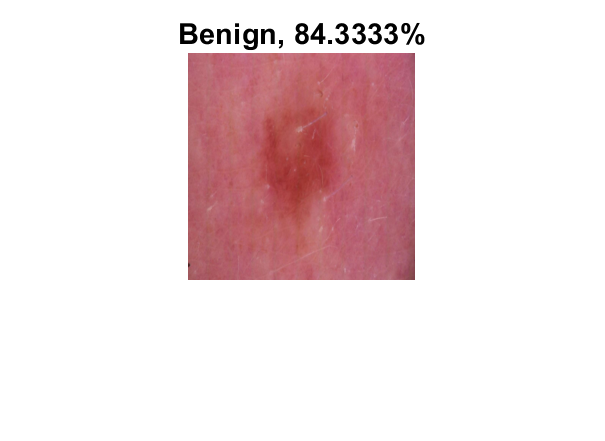

%Testing images
newImage1 = './BP.JPG'; %Benign Polarized
img1 = readAndPreprocessImage(newImage1);
YPred1 = predict(model2,img1);
[confidence1,idx1] = max(YPred1);
label1 = categories{idx1};
%Showing image and accuracy
imshow(img1)
title(string(label1) + ", " + num2str(100*confidence1) + "%");

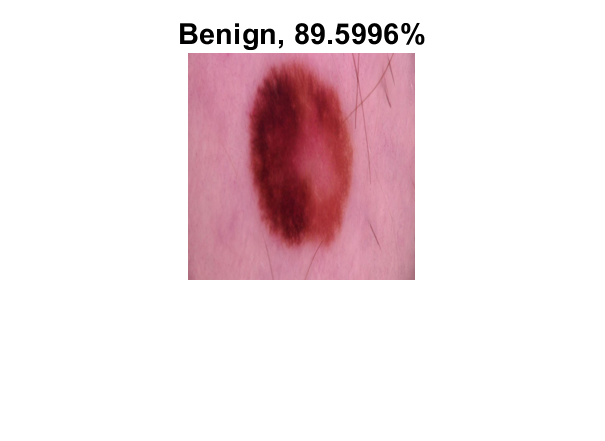

newImage2 = './MP.JPG'; %Malignant Polarized
img2 = readAndPreprocessImage(newImage2);
YPred2 = predict(model2,img2);
[confidence2,idx2] = max(YPred2);
label2 = categories{idx2};
%Showing image and accuracy
imshow(img2)
title(string(label2) + ", " + num2str(100*confidence2) + "%");

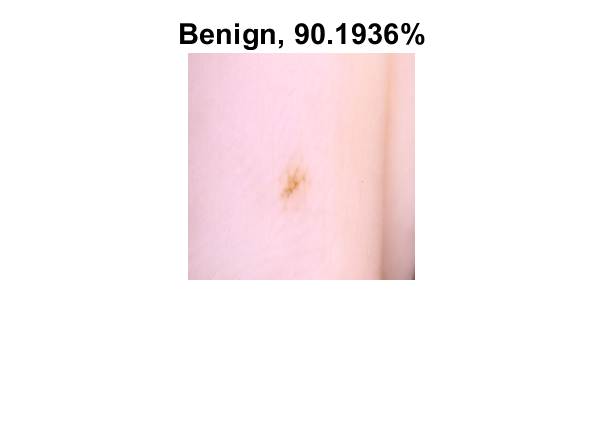

newImage3 = './BNP.JPG'; %Benign Non-Polarized
img3 = readAndPreprocessImage(newImage3);
YPred3 = predict(model2,img3);
[confidence3,idx3] = max(YPred3);
label3 = categories{idx3};
%Showing image and accuracy
imshow(img3)
title(string(label3) + ", " + num2str(100*confidence3) + "%");

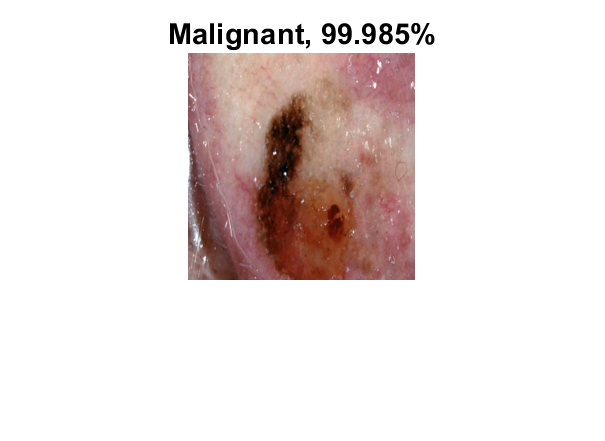

newImage4 = './MNP.JPG'; %Malignant Non-Polarized
img4 = readAndPreprocessImage(newImage4);
YPred4 = predict(model2,img4);
[confidence4,idx4] = max(YPred4);
label4 = categories{idx4};
%Showing image and accuracy
imshow(img4)
title(string(label4) + ", " + num2str(100*confidence4) + "%");

**Confusion Matrix**

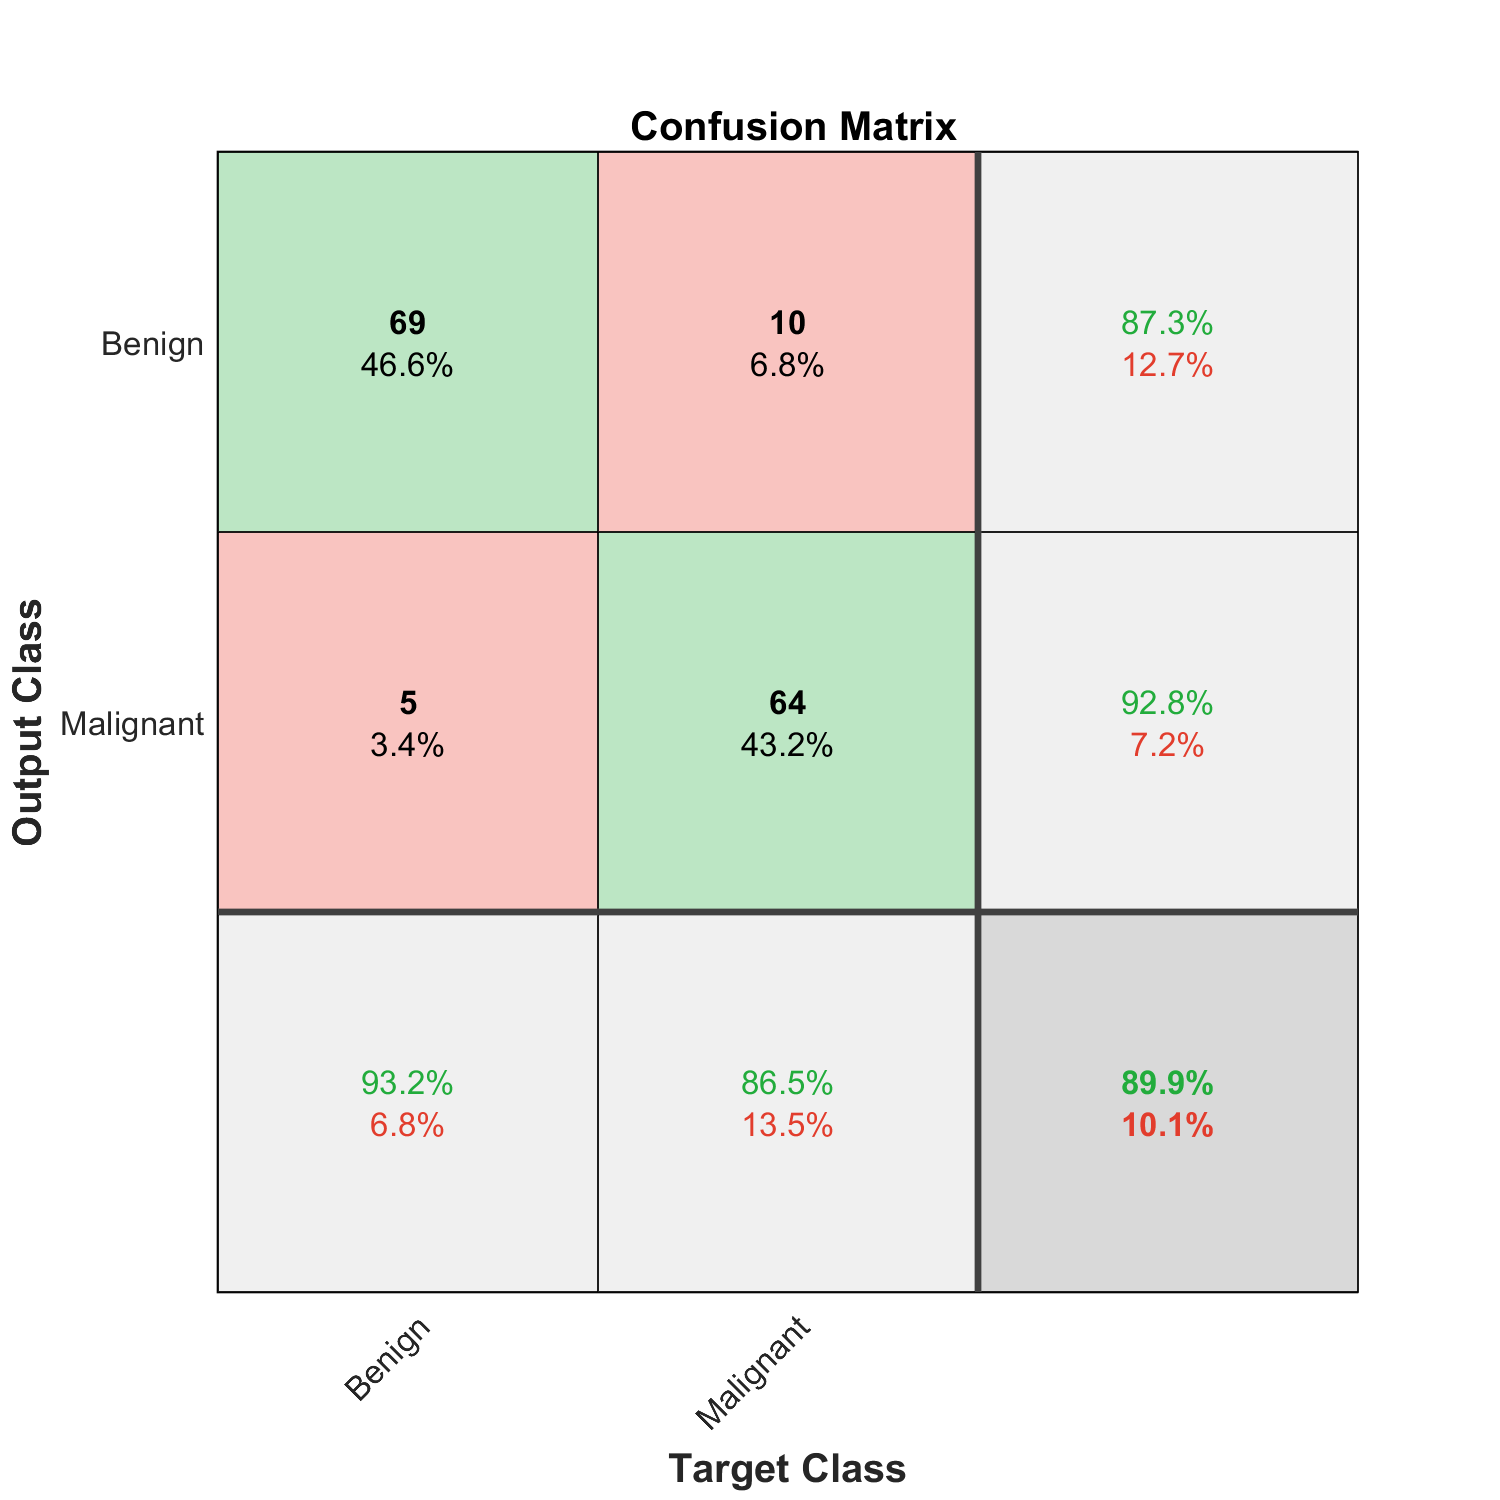

plotconfusion(YValidation, YPred)